**Physical Specs**

f = 30e3; % frequency of emitted sinusoid (pinger)
c = 1480;
lambda = c/f;
d = lambda/2; %lambda/2
H = 4;

dd = (0:1:H-1) * d;

arrival_ang_estimate = 45; % degrees arrival angle (changeable)
arrival_ang_rad = deg2rad(arrival_ang_estimate); % arrival angle in rad

**Create 4 mock hydrophone signals based on arrival angle**

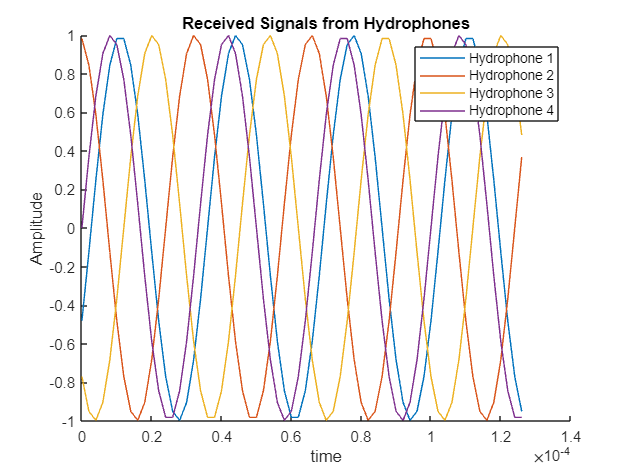

fs = 500e3; % sampling freq
t256 = 256/fs; % time to get 256 samples
dec_factor = 1; % downsampling factor

% Delays for each hydrophone in samples
delay = zeros(H,1);
for h = 1 : H
    delay(h) = ceil(abs((((h-1) * d * cos(arrival_ang_rad)) / c) * fs));
end

max_delay = (d * sin(pi/2)) / c; % delay of last hydro if hit endfire
max_delay_samples = ceil(max_delay * fs);

n = 0:1/fs:t256-1/fs; % discrete time
N = length(n);

% Generate ping
signal = sin(2*pi*f*n); % pinger signal (biased to 2.5v)

% Hydro ~ (4,length(t)) array, each row is a signal received by each hydrophone
hydro = zeros(H, N); 

% Set refmic as mic that gets hit first and apply delays accordingly
if arrival_ang_estimate < 90
    for h = 1 : H
        hydro(H-h+1,:) = sin(2*pi*f*(n-delay(h)*1/fs));
    end
    refmic = hydro(H,:);
else
    for h = 1 : H
        hydro(h,:) = sin(2*pi*f*(n-delay(h)*1/fs));
    end
    refmic = hydro(1,:);
end

% Add AWGN noise to signals
signalPower = rms(hydro(:,1))^2;
[hydroNoisey, noiseVar] = awgn(hydro,0,'measured'); % 2nd parameter is SNR

% Decimate hydrophone signals
hydro_dec = zeros(H,N/dec_factor);
for h = 1 : H
    hydro_dec(h,:) = hydroNoisey(h,1:dec_factor:end);
end

% Normalize hydrophone data [-1, 1]
maximum = max(hydro_dec,[],"all");
minimum = min(hydro_dec,[],"all");
hydro_dec = (hydro_dec - minimum)/(maximum - minimum);
hydro_dec = 2 * hydro_dec - 1;

% Save to raw hydro data .mat file
%save('/Users/a.j.beckmann/ajb-projects/APR_Personal/Bartlett-Algo/Test-data/raw_hydro_data.mat','hydro_dec')

% Plot decimated hydrophone signals
figure;
hold on;
for i = 1:H
    plot(n(1:int8(N/4)), real(hydro(i, 1:int8(N/4))), 'DisplayName', ['Hydrophone ' num2str(i)]);
end
hold off;
title('Received Signals from Hydrophones');
xlabel('time');
ylabel('Amplitude');
legend;

**Bartlett Algo**

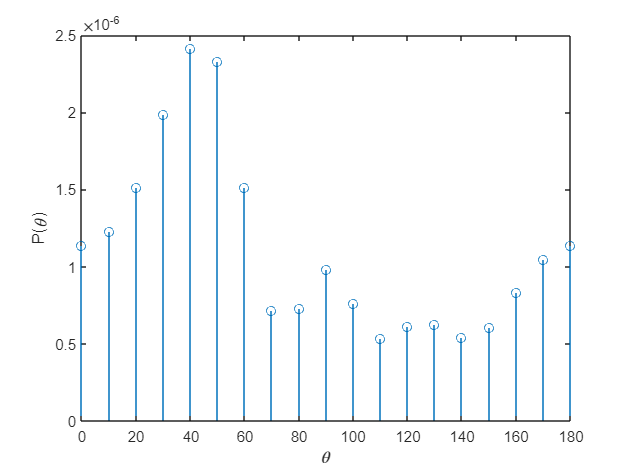

theta = (0:10:180) * pi / 180; % define angle range
k = 2*pi/lambda; % constant

% Create array manifold (for each angle in theta, there is a 4x1 steering vector s(theta))
a = zeros(H,length(theta)); % allocate space for array manifold
for i=1:length(theta)
    a(:,i) = exp(1j*k*dd*cos(theta(i))); % s(theta)
end

% Hilbert Transform
negativeFreqs = ceilDiv(length(hydro_dec),2):length(hydro_dec);
fourier = fft(hydro_dec,[],2)/N; % scale fft to have Re and Im components between -1/+1
fourier(:,negativeFreqs) = zeros(4,length(negativeFreqs)); % zero negative frequencies
hydro_dec = ifft(fourier,[],2); % hydro_dec now complex

% Save fourier data (split real and imaginary components)
export_fourier = zeros(8, 256);
for i = 1:4
    export_fourier(2*i - 1, :) = real(fourier(i, :));
    export_fourier(2*i, :) = imag(fourier(i, :));
end
%save('/Users/a.j.beckmann/ajb-projects/APR_Personal/Bartlett-Algo/Test-data/fft_data.mat','export_fourier')

% Save post hilbert transform hydrophone data (split real and imaginary components)
export_post_hilbert_data = zeros(8, 256);
for i = 1:4
    export_post_hilbert_data(2*i - 1, :) = real(hydro_dec(i, :));
    export_post_hilbert_data(2*i, :) = imag(hydro_dec(i, :));
end
%save('/Users/a.j.beckmann/ajb-projects/APR_Personal/Bartlett-Algo/Test-data/post_hilbert_hydro_data.mat','export_post_hilbert_data')

% Create R
R = zeros(H,H); % allocate space for x(t)*x(t)^H

for i = 1 : length(hydro_dec)
    R = R + hydro_dec(:,i) * hydro_dec(:,i)';
end

R = R / N; % normalize by number of samples

% Calculate P(theta) for every theta
P = zeros(1,length(theta));
magP = zeros(1,length(theta));

% Normalize P by s(theta)^H*s(theta)
for i=1:length(theta)
    P(i) = a(:,i)'*R*a(:,i) / (a(:,i)'*a(:,i));
    magP(i) = norm(P(i)); 
end

figure;
stem(theta*180/pi,magP); xlabel('\theta'); ylabel('P(\theta)');

[maxP, I] = max(magP); % max values is arrival angle estimate
arrival_ang_estimate =  theta(I) * 180/pi % estimate in degrees

arrival_ang_estimate = 40